# Tutorial for the Mass-Damper-Spring (MadS) solver: Statics

This tutorial shows how work with  the MaDS solver: how to set up the data,  construct and solve the models.

The first step is to sketch the structure, find the locations of the joints, and list the joints as they are connected by the springs. This can be also easily accomplished with commercial or open-source  structural analysis software.  Here we use Abaqus.  Figure 1 shows the designed structure in  the Abaqus  environment.

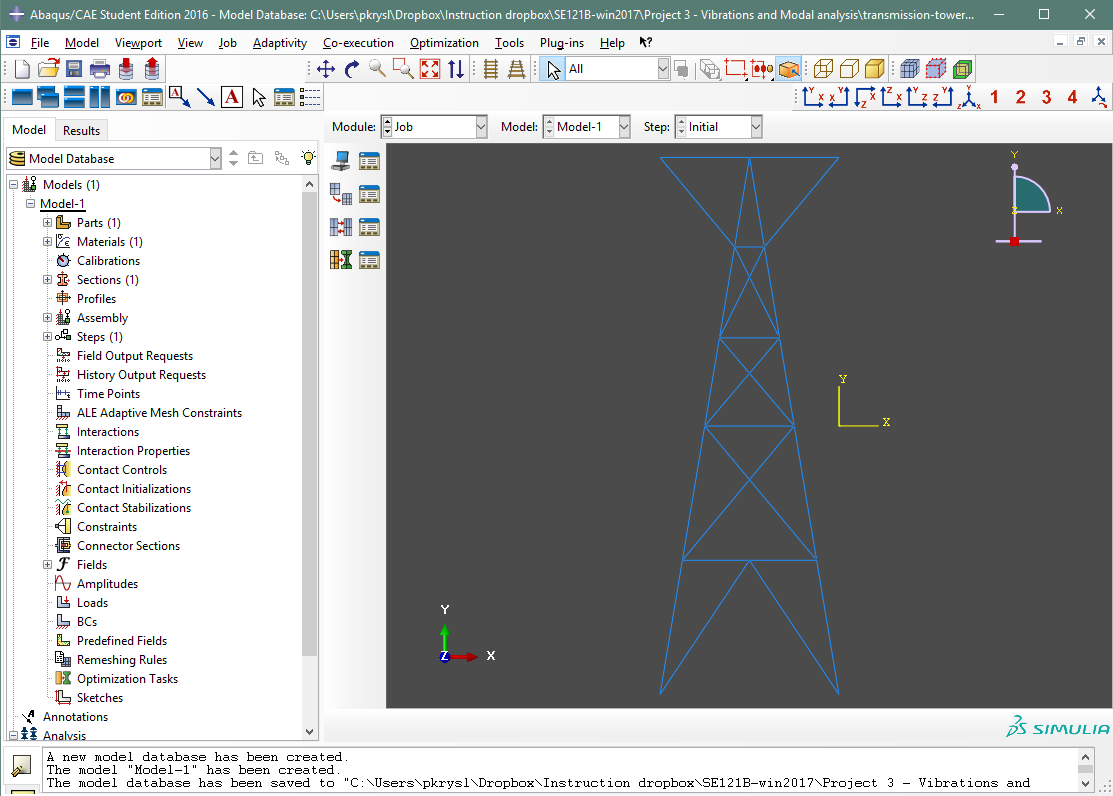

Figure 1.  Model of a transmission tower in Abaqus.

The  model file Job-1.inp will hold all the geometrical information we need.  Figure 2 shows the partial listing.

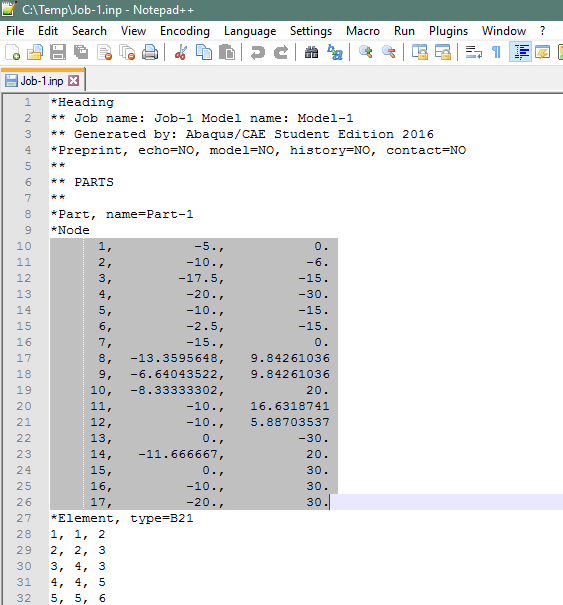

Figure 2.  Partial listing of the file Job-1.inp written out  by Abaqus.

This data can be copied and pasted into Matlab.  Here is the array that will define the locations of the joints:

Joints=[
    1,          -5.,           0.
    2,         -10.,          -6.
    3,        -17.5,         -15.
    4,         -20.,         -30.
    5,         -10.,         -15.
    6,         -2.5,         -15.
    7,         -15.,           0.
    8,  -13.3595648,   9.84261036
    9,  -6.64043522,   9.84261036
    10,  -8.33333302,          20.
    11,         -10.,   16.6318741
    12,         -10.,   5.88703537
    13,           0.,         -30.
    14,   -11.666667,          20.
    15,           0.,          30.
    16,         -10.,          30.
    17,         -20.,          30.];

The first column is the joint number, followed by the X and Y coordinate.  The array that defines the springs by listing the first and the second joint connected by the spring is copied and pasted next:

Springs =[
    1, 1, 2
    2, 2, 3
    3, 4, 3
    4, 4, 5
    5, 5, 6
    6, 1, 6
    7, 7, 1
    8, 7, 8
    9, 8, 9
    10, 10,  9
    11, 10, 11
    12, 11,  8
    13, 12,  8
    14,  9, 12
    15, 6, 2
    16, 3, 5
    17, 3, 7
    18,  5, 13
    19,  6, 13
    20, 9, 1
    21, 12,  7
    22,  1, 12
    23,  8, 14
    24,  9, 11
    25, 15, 10
    26, 16, 15
    27, 16, 10
    28, 10, 14
    29, 11, 14
    30, 2, 7
    31, 14, 17
    32, 14, 16
    33, 17, 16];

As above, the first column lists the spring number, followed by the first and second joint number.  These joint numbers point into the Joints  array. Spring 13  connects joints 12 and 8.  To get the coordinates of the joints connected by spring 13 we do:

Joints([12,8],2:3)

ans =   -10.0000    5.8870
  -13.3596    9.8426


The MaDS solver does not need the first column  from these two arrays.  It expects the locations of the joints to be in an array of N rows and 2 columns.

X=  Joints(:,2:3)

X =    -5.0000         0
  -10.0000   -6.0000
  -17.5000  -15.0000
  -20.0000  -30.0000
  -10.0000  -15.0000
   -2.5000  -15.0000
  -15.0000         0
  -13.3596    9.8426
   -6.6404    9.8426
   -8.3333   20.0000


Further, the connectivity of the springs is expected in an array of two columns:

kconn= Springs(:,2:3)

kconn =      1     2
     2     3
     4     3
     4     5
     5     6
     1     6
     7     1
     7     8
     8     9
    10     9


***Note: ***

- The two arrays, X and kconn, define the geometry of the model.  They could have just as well been constructed by hand. Use of CAD software is not required. It just makes the process somewhat smoother.

- The physical units for all the quantities needs to be consistent.  They are implied (we make no reference to physical units anywhere).

We need to define the constants of the springs.  If the springs are representations of rod-like structural members,  their stiffness will be $k=\frac{E\text{ }A}{L}$, where $E$ is the Young's  modulus, $A$ is the cross-sectional area, and $L$ is the length of the member.  If we assume for simplicity that all the members are the same material with the same cross-sectional area,  we can compute the stiffness constants of all the springs in one loop.


% Young's modulus
E=7.17e10;% Pascal
Area=0.04^2;% meters squared
k=[];
for  i =1:size(kconn,1)
    k(i)=E*Area/MaDS.len(X(kconn(i,:),:));
end

The MaDS.len() function is the first reference to the solver.  It is a convenience function that can compute the length of a spring based on the joint-location array X and the joint numbers (for spring number i). The array X(kconn(i,:),:) has two rows,  one for each joint of the spring.   For instance, for spring 4:

X(kconn(4,:),:)

ans =    -20   -30
   -10   -15


Now we can plot  the structure as it is currently understood by MaDS. The class for visualizing mass-damper-spring structures is SimPl.  It understands the data structures as defined above.  To find out more about SimPl run 

SimPl.demo1()

and inspect the code.  Back to the drawing of the current structure:

f=figure;% Create figure
ax=gca;% Draw into these axes
axis equal
JointRadius= 4;% Joints are represented with circles of this radius
SpringWidth= 0.;% Ignore this for the moment
SimPl.draw_springs(ax,X,kconn,SpringWidth,0.7*[1,0,0])
SimPl.draw_joints(ax,X,JointRadius,0.1*[1,1,1]);

We can also add the numbers of the joints:

SimPl.draw_joint_numbers(ax,X,'k',14,[1.2, 0.8])

and perhaps now also the numbers of the springs:

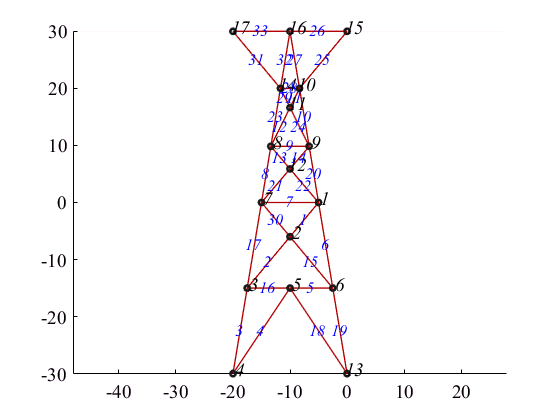

SimPl.draw_spring_numbers(ax,X,kconn,'b',12,[-0.2, 0.18])

Next  we need to define the degrees of freedom: each joint can move horizontally (x-degree of freedom)  and vertically (y-degree of freedom).  Consequently to number the degrees of freedom we assign  each degree of freedom successive integer number, starting from 1.  The  unknown degrees of freedom will be numbered first, followed by the degrees of freedom that are known.  A pin support of a joint means  both degrees of freedom at that joint are known (for a fixed pin they are known to be zero).

In the transmission tower structure the joints at the bottom, 4 and 13, will be pinned. Therefore the numbering of the degrees of freedom can go as follows: The two-dimensional array to hold the  numbers of the degrees of freedom is created full of zeros.

dof=zeros(size(X));

Then we number the free degrees of freedom.  We loop through all joints, but skipping joints 4 and 13.

nfreedof=1;
for  i =setdiff(1:size(X,1),[4,13])
    dof(i,1)=nfreedof; nfreedof=nfreedof+1;
    dof(i,2)=nfreedof; nfreedof=nfreedof+1;
end
nfreedof=nfreedof-1; % Backup one

This gives the current numbering, only the free degrees of freedom mind you, as:

dof

dof =      1     2
     3     4
     5     6
     0     0
     7     8
     9    10
    11    12
    13    14
    15    16
    17    18


The number of free degrees of freedom must be

2*(size(X,1) -2)

ans = 30

nfreedof

nfreedof = 30

Next we number the known degrees of freedom at joints 4 and 13.

ndof=nfreedof+1;
for  i =[4,13]
    dof(i,1)=ndof; ndof=ndof+1;
    dof(i,2)=ndof; ndof=ndof+1;
end

The  completed array of numbers of degrees of freedom is

dof

dof =      1     2
     3     4
     5     6
    31    32
     7     8
     9    10
    11    12
    13    14
    15    16
    17    18


Now we are ready to solve a deformation problem.  First statics, with a vertical load applied at joint 15.

% Applied static force
AppliedF=zeros(size(X));
AppliedF(15,2)=-5000;% downward-directed  force

Here is a graphical representation of the model. Note that we split the joints into two groups: the ones that are free and the ones that are pinned.  The pinned joints are rendered with bigger circles.

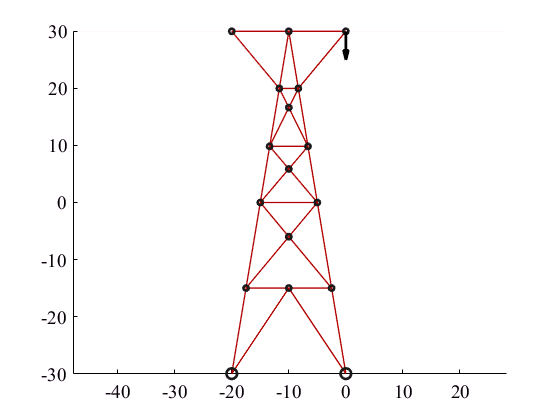

f=figure;% Create figure
ax=gca;% Draw into these axes
axis equal
JointRadius= 4;% Joints are represented with circles of this radius
SpringWidth= 0.;% Ignore this for the moment
SimPl.draw_springs(ax,X,kconn,SpringWidth,0.7*[1,0,0])
SimPl.draw_joints(ax,X(setdiff(1:size(X,1),[4,13]),:),JointRadius,0.1*[1,1,1]);
SimPl.draw_joints(ax,X([4,13],:),2*JointRadius,0.1*[1,1,1]);
SimPl.draw_forces(ax,X,AppliedF,0.7*[0,0,1],1/1000)

Now the solution can be attempted.  We need to construct the stiffness matrix and the load vector.  The stiffness matrix:

K=MaDS.stiffness(X,k,kconn,dof);

The load vector.

F=MaDS.applied_forces(AppliedF,dof);

Note  that both the stiffness matrix and the load vector are of dimension  corresponding to all the degrees of freedom, not just the free ones.

nfreedof, size(K), size(F),

nfreedof = 30

ans =     34    34


ans =     34     1


Because of the numbering of the degrees of freedom, the free degrees of freedom first, we can easily extract just the part of the stiffness matrix and of the  load vector that corresponds to the free degrees of freedom.

K=K(1:nfreedof,1:nfreedof);
F=F(1:nfreedof);

The solution of the equilibrium equations is a vector of displacements only along the free degrees of freedom:

U=K\F

U =     0.0011
   -0.0014
    0.0001
   -0.0005
   -0.0003
    0.0002
   -0.0003
         0
   -0.0003
   -0.0008


The deformed shape can be now visualized. The joints in the deformed shape will be displaced by the components of the vector U, multiplied with some scaling factor to make the deformations  easily discernible by the eye. The displaced positions of the joints are represented by an array of the same shape as X.

scale =500;
Xdeformed=X + scale*MaDS.scatter_vector(U,dof);

The deformed structure can now be  displayed.

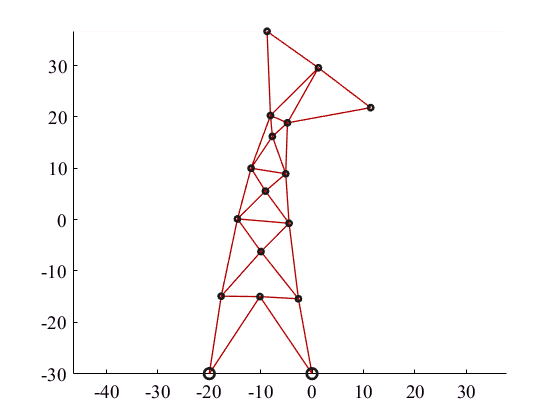

f=figure;% Create figure
ax=gca;% Draw into these axes
axis equal
JointRadius= 4;% Joints are represented with circles of this radius
SpringWidth= 0.;% Ignore this for the moment
SimPl.draw_springs(ax,Xdeformed,kconn,SpringWidth,0.7*[1,0,0])
SimPl.draw_joints(ax,Xdeformed(setdiff(1:size(X,1),[4,13]),:),JointRadius,0.1*[1,1,1]);
SimPl.draw_joints(ax,Xdeformed([4,13],:),2*JointRadius,0.1*[1,1,1]);

Or, for a horizontal force at joint 1.

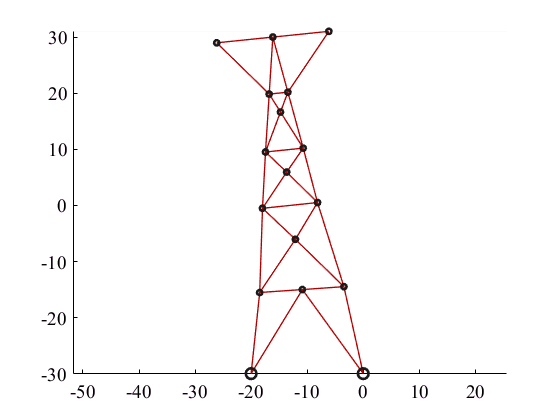

AppliedF=zeros(size(X));
AppliedF(1,1)=-10000;% horizontal force
F=MaDS.applied_forces(AppliedF,dof);
F=F(1:nfreedof);
U=K\F;
scale =500;
Xdeformed=X + scale*MaDS.scatter_vector(U,dof);% These are the locations after deformation
f=figure;% Create figure
ax=gca;% Draw into these axes
axis equal
JointRadius= 4;% Joints are represented with circles of this radius
SpringWidth= 0.;% Ignore this for the moment
SimPl.draw_springs(ax,Xdeformed,kconn,SpringWidth,0.7*[1,0,0])
SimPl.draw_joints(ax,Xdeformed(setdiff(1:size(X,1),[4,13]),:),JointRadius,0.1*[1,1,1]);
SimPl.draw_joints(ax,Xdeformed([4,13],:),2*JointRadius,0.1*[1,1,1]);

We can overlay the deformed structure on top of the undeformed one for reference.

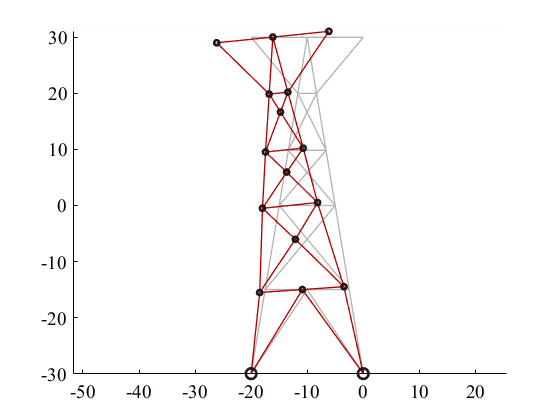

f=figure;% Create figure
ax=gca;% Draw into these axes
axis equal
JointRadius= 4;% Joints are represented with circles of this radius
SpringWidth= 0.;% Ignore this for the moment
SimPl.draw_springs(ax,X,kconn,SpringWidth,0.7*[1,1,1])
SimPl.draw_springs(ax,Xdeformed,kconn,SpringWidth,0.7*[1,0,0])
SimPl.draw_joints(ax,Xdeformed(setdiff(1:size(X,1),[4,13]),:),JointRadius,0.1*[1,1,1]);
SimPl.draw_joints(ax,Xdeformed([4,13],:),2*JointRadius,0.1*[1,1,1]);

We could also compute and visualize the axial forces in the springs (truss members). The force is computed as $N=k\cdot \Delta L$, where $k$ is the stiffness coefficient of the spring and $\Delta L$ is the elongation of the spring. The elongation is computed from the displacements of the two joints. The array of joint displacements is computed as

u=MaDS.scatter_vector(U,dof);

The displacements of the two joints connected by spring 4 can be picked out from u as

u(kconn(4,:),:)

ans =          0         0
   -0.0017         0


The elongation of the spring that connects joints $m$ and $n$ is computed by projecting the displacements at the joints into the direction of the line that connects the joints $m$ and $n$:

dL=MaDS.elong(X(kconn(4,:),:),u(kconn(4,:),:))

dL = -9.4433e-04

Apparently, spring 4 is shortened by the deformation since the elongation is negative. The axial force in the spring is computed as

N=k(4)*dL

N = -6.0093e+03

so we find spring 4 to be under a compressive force. We can compute the axial forces for the entire structure as

N=zeros(size(k));
for  i =1:size(kconn,1)
    N(i)=k(i)*MaDS.elong(X(kconn(i,:),:),u(kconn(i,:),:));
end

The minimum and maximum values of the axial forces can now be mapped into a color range.

min(N),max(N)

ans = -1.0138e+04

ans = 1.0138e+04

For that purpose we will use the utility class in AETNA, data_colormap:

dcm = data_colormap (struct( 'range', [min(N),max(N)], 'colormap', parula))

dcm =   data_colormap with properties:

        rmin: -1.0138e+04
        rmax: 1.0138e+04
    colormap: [64×3 double]


With the data-to-color mapping we can render the axial forces.  First we draw  the undeformed structure as before:

f=figure;% Create figure
ax=gca;% Draw into these axes
axis equal
JointRadius= 4;% Joints are represented with circles of this radius
SpringWidth= 4;% Thickness of the line
SimPl.draw_springs(ax,X,kconn,SpringWidth,0.7*[1,1,1])

Next we render the axial forces in the springs.  Note that we draw each spring individually, kconn(i,:) refers to a single spring i.

for  i =1:size(kconn,1)
    SimPl.draw_springs(ax,Xdeformed,kconn(i,:),SpringWidth,dcm.map_data(N(i)))
end

The plot can be now finished off with the  symbols for the joints.

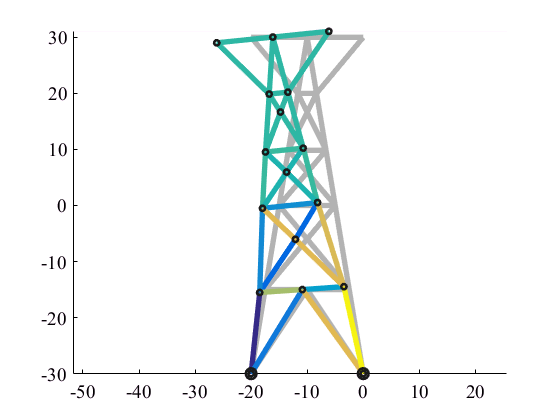

SimPl.draw_joints(ax,Xdeformed,JointRadius,0.1*[1,1,1]);
SimPl.draw_joints(ax,Xdeformed([4,13],:),2*JointRadius,0.1*[1,1,1]);

The yellow colors correspond to tensile forces, the blue corresponds to compressive forces, and the greenish color in between stands essentially for zero forces in the upper portion of the structure which for this particular loading moves as a rigid body.

## Summary

This tutorial was aimed at statics (equilibrium) problems.  The subsequent tutorial deals with dynamics.